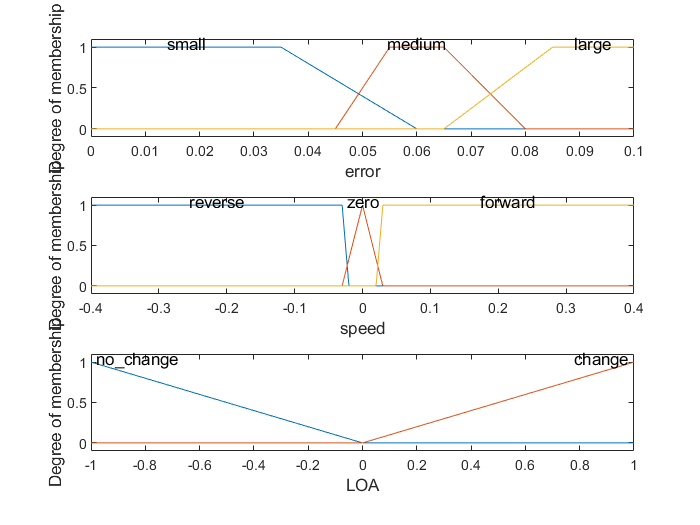

%{
recreation of fuzzy inference system (FIS) called Expert-guided Mixed-Initiative Control Switcher (EMICS)
as presented in "Chiou M., Hawes N., & Stolkin R. (2021). Mixed-initiative Variable Autonomy for Remotely 
Operated Mobile Robots. ACM Transactions on Human-Robot Interaction, 10(4), 1–34.https://doi.org/10.1145/3472206" 
Suggested for those who do not possess FuzzyLite should they want to evaluate the fuzzy-logic inference system. 
%}


% create EMICS - specified system's properties in advance
emicsFIS = mamfis('Name', 'EMICS', ...
                'NumInputs', 2, 'NumInputMFs', 3, ...
                'NumOutputs', 1, 'NumOutputMFs', 2, ...
                'AddRule', 'none' ...
                );
% choose Largest of Maxima (LOM) defuzzification method 
emicsFIS.DefuzzificationMethod = "lom";

% INPUT 1 - 'goal directed motion error'
emicsFIS.Inputs(1).Name = 'error';
emicsFIS.Inputs(1).Range = [0 0.1]; % m/sec
emicsFIS.Inputs(1).MembershipFunctions(1).Name = 'small';
emicsFIS.Inputs(1).MembershipFunctions(1).Type = 'trapmf';
emicsFIS.Inputs(1).MembershipFunctions(1).Parameters = [0 0 0.035 0.06];
emicsFIS.Inputs(1).MembershipFunctions(2).Name = 'medium';
emicsFIS.Inputs(1).MembershipFunctions(2).Type = 'trapmf';
emicsFIS.Inputs(1).MembershipFunctions(2).Parameters = [0.045 0.055 0.065 0.08];
emicsFIS.Inputs(1).MembershipFunctions(3).Name = 'large';
emicsFIS.Inputs(1).MembershipFunctions(3).Type = 'trapmf';
emicsFIS.Inputs(1).MembershipFunctions(3).Parameters = [0.065 0.085 0.1 0.1];

% INPUT 2 - 'speed'
emicsFIS.Inputs(2).Name = 'speed'; % m/sec
emicsFIS.Inputs(2).Range = [-0.4 0.4];
emicsFIS.Inputs(2).MembershipFunctions(1).Name = 'reverse';
emicsFIS.Inputs(2).MembershipFunctions(1).Type = 'trapmf';
emicsFIS.Inputs(2).MembershipFunctions(1).Parameters = [-0.4 -0.4 -0.03 -0.02];
emicsFIS.Inputs(2).MembershipFunctions(2).Name = 'zero';
emicsFIS.Inputs(2).MembershipFunctions(2).Type = 'trimf';
emicsFIS.Inputs(2).MembershipFunctions(2).Parameters = [-0.03 0 0.03];
emicsFIS.Inputs(2).MembershipFunctions(3).Name = 'forward';
emicsFIS.Inputs(2).MembershipFunctions(3).Type = 'trapmf';
emicsFIS.Inputs(2).MembershipFunctions(3).Parameters = [0.02 0.03 0.4 0.4];

% OUTPUT - Decision on Level of Autonomy (LOA)
emicsFIS.Outputs(1).Name = 'LOA';
emicsFIS.Outputs(1).Range = [-1.0 1.0];
emicsFIS.Outputs(1).MembershipFunctions(1).Name = 'no_change';
emicsFIS.Outputs(1).MembershipFunctions(1).Type = 'trimf';
emicsFIS.Outputs(1).MembershipFunctions(1).Parameters = [-1 -1 0];
emicsFIS.Outputs(1).MembershipFunctions(2).Name = 'change';
emicsFIS.Outputs(1).MembershipFunctions(2).Type = 'trimf';
emicsFIS.Outputs(1).MembershipFunctions(2).Parameters = [0 1 1];

% plot membership functions
subplot(3, 1, 1)
plotmf(emicsFIS, 'input', 1, 1000);
subplot(3, 1, 2)
plotmf(emicsFIS, 'input', 2, 1000);
subplot(3, 1, 3)
plotmf(emicsFIS, 'output', 1, 1000);

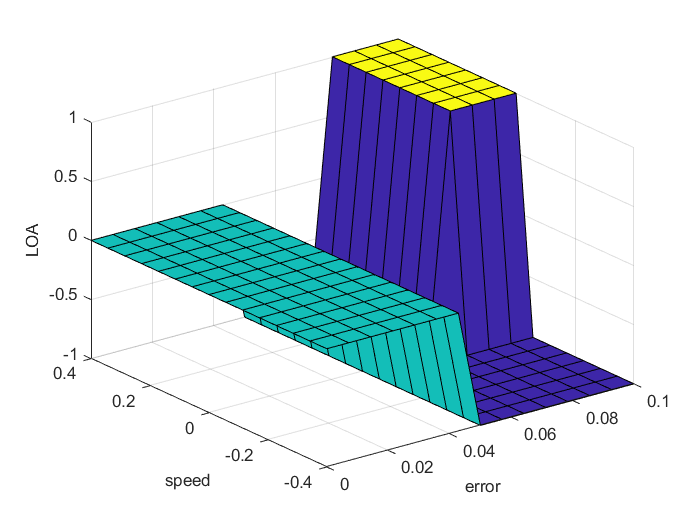

% Specify rules
rulestxt = ["If error is small or error is medium then LOA is no_change";
            "If error is large and speed is not reverse then LOA is change";
            "If speed is reverse and error is large then LOA is no_change"];

figure
emicsFIS = addRule(emicsFIS, rulestxt);

% generate input-output mapping
gensurf(emicsFIS);

% The output values, Z, are the FIS output evaluated at the corresponding X and Y grid points
[X,Y,Z] = gensurf(emicsFIS, gensurfOptions("NumGridPoints", 100));

% evaluate the output of EMICS for a given input combination
error_value = 0.08;
speed_value = 0.3;
evalfis(emicsFIS,[error_value speed_value])

ans = 1